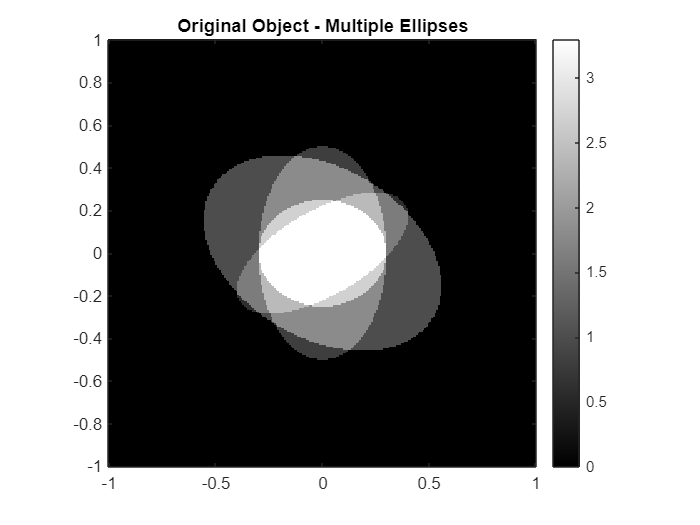

% OPTI 512L
% Mohanbabu Mani
% LAB 9

%1.


n_bins = 128;                 
p_max = 1;                    
p = linspace(-p_max, p_max, n_bins);
angle_sets = [10, 60, 180];    
ellipses = [
    0.6,  0.4,  30,  1.0;
    0.5,  0.3,  90,  0.8;
    0.45, 0.2, 150,  0.6;
    0.3,  0.25,  0,  0.9;
];

n_ellipses = size(ellipses,1);
grid_size = 256;
x_range = linspace(-1,1,grid_size);
y_range = linspace(-1,1,grid_size);
[X, Y] = meshgrid(x_range, y_range);

f_object = zeros(grid_size, grid_size);

for ell_idx = 1:n_ellipses
    A = ellipses(ell_idx,1);
    B = ellipses(ell_idx,2);
    alpha = ellipses(ell_idx,3) * pi / 180;
    beta = ellipses(ell_idx,4);
    X_rot = X*cos(alpha) - Y*sin(alpha);
    Y_rot = X*sin(alpha) + Y*cos(alpha);

    inside = (X_rot/A).^2 + (Y_rot/B).^2 <= 1;
    f_object = f_object + beta * inside;
end

figure;
imagesc(x_range, y_range, f_object);
colormap(gray); colorbar;
title('Original Object - Multiple Ellipses');
axis image; axis xy;

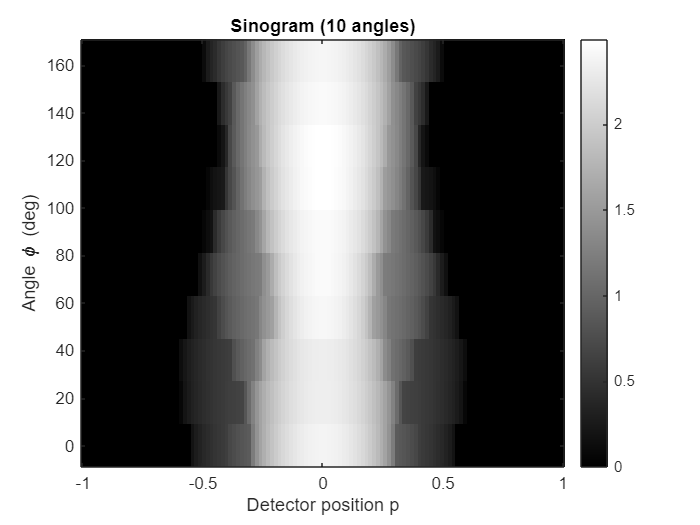

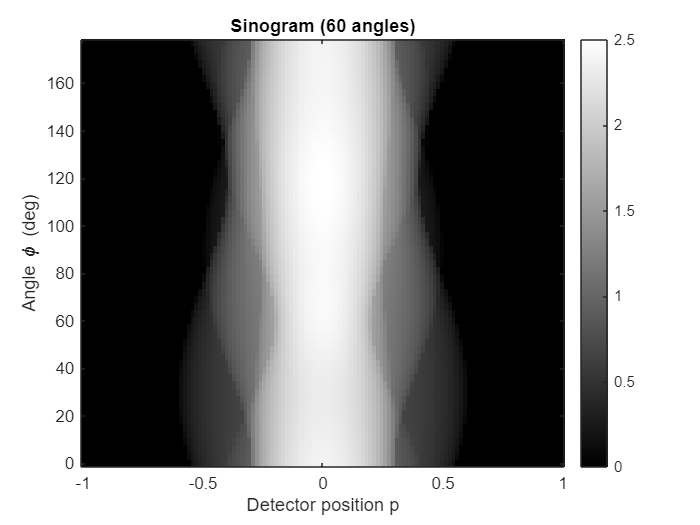

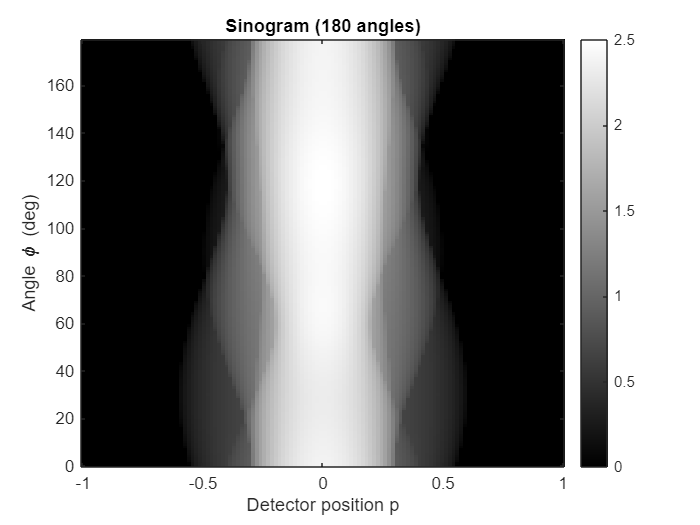


for aidx = 1:length(angle_sets)
    n_angles = angle_sets(aidx);
    angles_deg = linspace(0,180,n_angles+1); angles_deg = angles_deg(1:end-1); 
    angles_rad = angles_deg * pi / 180;
    sinogram = zeros(n_angles, n_bins);

    for ang_idx = 1:n_angles
        phi = angles_rad(ang_idx);
        for ell_idx = 1:n_ellipses
            A = ellipses(ell_idx,1);
            B = ellipses(ell_idx,2);
            alpha = ellipses(ell_idx,3) * pi / 180;
            beta = ellipses(ell_idx,4);

            cos_d = cos(phi - alpha);
            sin_d = sin(phi - alpha);
            denom = A^2 * cos_d^2 + B^2 * sin_d^2;

            for p_idx = 1:n_bins
                p_val = p(p_idx);
                discrim = denom - p_val^2;
                if discrim >= 0
                    proj_val = (2*beta*A*B/denom) * sqrt(discrim);
                    sinogram(ang_idx, p_idx) = sinogram(ang_idx, p_idx) + real(proj_val);
                end
            end
        end
    end

    save(sprintf('sinogram_%d_angles.mat', n_angles), 'sinogram', 'angles_deg', 'p', 'ellipses');

    figure;
    imagesc(p, angles_deg, sinogram);
    colormap(gray); colorbar;
    xlabel('Detector position p');
    ylabel('Angle \phi (deg)');
    title(sprintf('Sinogram (%d angles)', n_angles));
    axis xy;
end

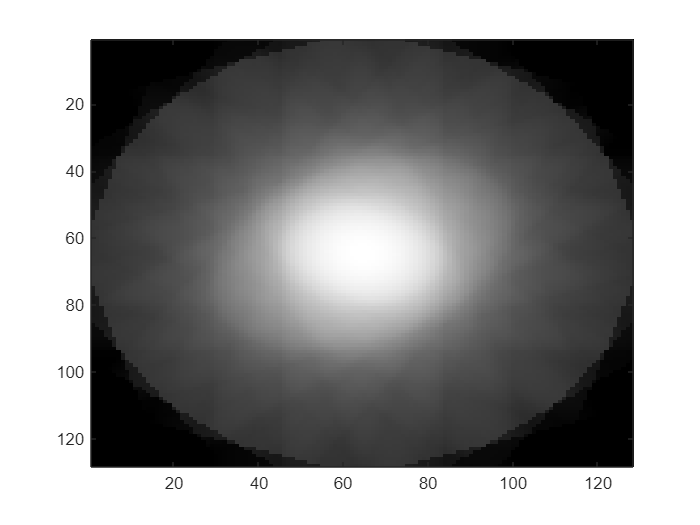

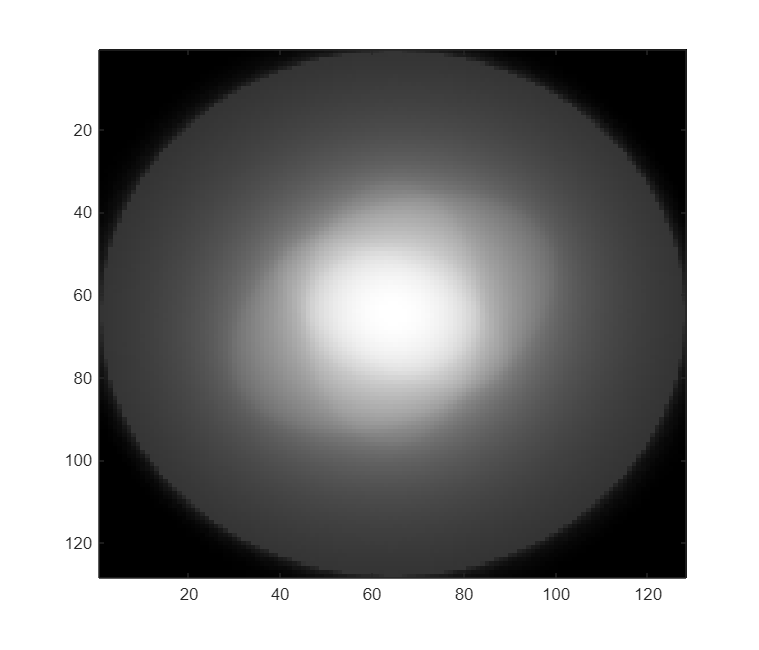

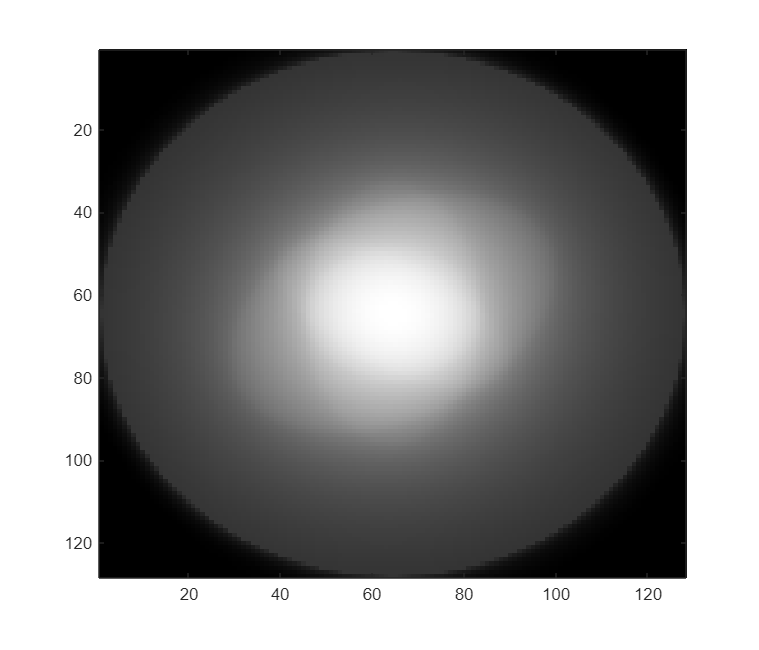

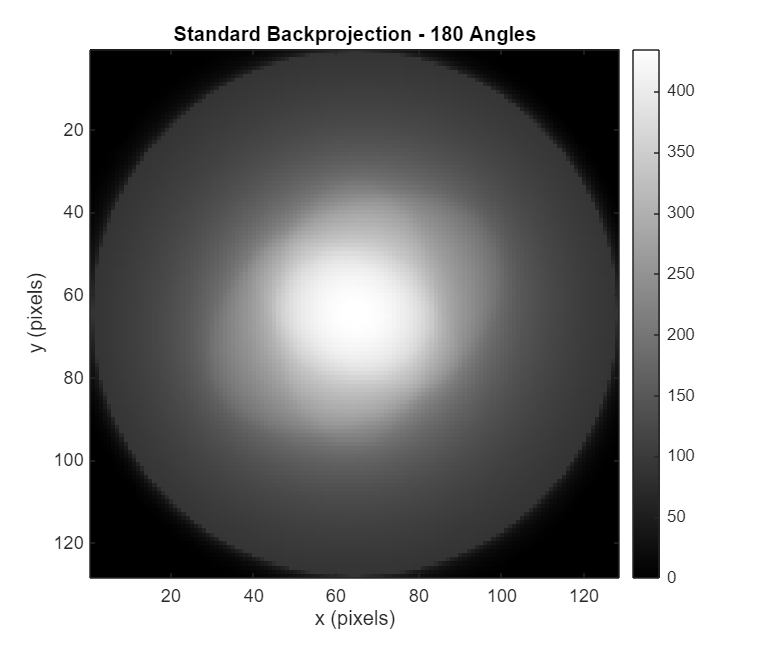

% 2.

angle_sets = [10, 60, 180];

for angle_idx = 1:length(angle_sets)
    n_angles = angle_sets(angle_idx);
    
    filename = sprintf('sinogram_%d_angles.mat', n_angles);
    
    if ~exist(filename, 'file')
        error('File %s not found. Run Problem 1 first to generate sinograms.', filename);
    end
    
    data = load(filename);
    sinogram = data.sinogram;
    angles_deg = data.angles_deg;
    [n_ang, n_bins] = size(sinogram);
    f_backproj = backproj(sinogram, angles_deg);
    
    output_filename = sprintf('backproj_%d_angles.mat', n_angles);
    save(output_filename, 'f_backproj', 'n_angles');

    figure('Name', sprintf('Backprojection - %d angles', n_angles), ...
           'Position', [100 + angle_idx*50, 100 + angle_idx*50, 700, 600]);
    imagesc(f_backproj);
    colormap(gray);
    colorbar;
    title(sprintf('Standard Backprojection - %d Angles', n_angles), ...
          'FontSize', 14, 'FontWeight', 'bold');
    xlabel('x (pixels)', 'FontSize', 12);
    ylabel('y (pixels)', 'FontSize', 12);
    axis image;
    set(gca, 'FontSize', 11);
    
end

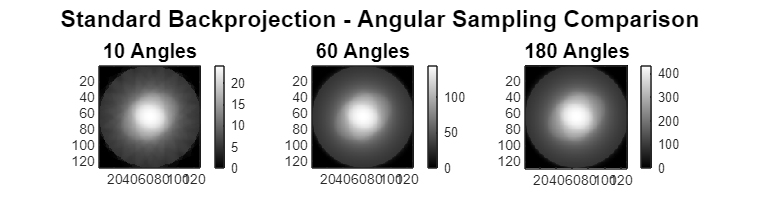


figure('Name', 'Backprojection Comparison', 'Position', [200, 50, 1400, 400]);

for angle_idx = 1:length(angle_sets)
    n_angles = angle_sets(angle_idx);
    data = load(sprintf('backproj_%d_angles.mat', n_angles));
    f_backproj = data.f_backproj;
    
    subplot(1, 3, angle_idx);
    imagesc(f_backproj);
    colormap(gray);
    colorbar;
    title(sprintf('%d Angles', n_angles), 'FontSize', 12, 'FontWeight', 'bold');
    axis image;
end

sgtitle('Standard Backprojection - Angular Sampling Comparison', ...
        'FontSize', 14, 'FontWeight', 'bold');

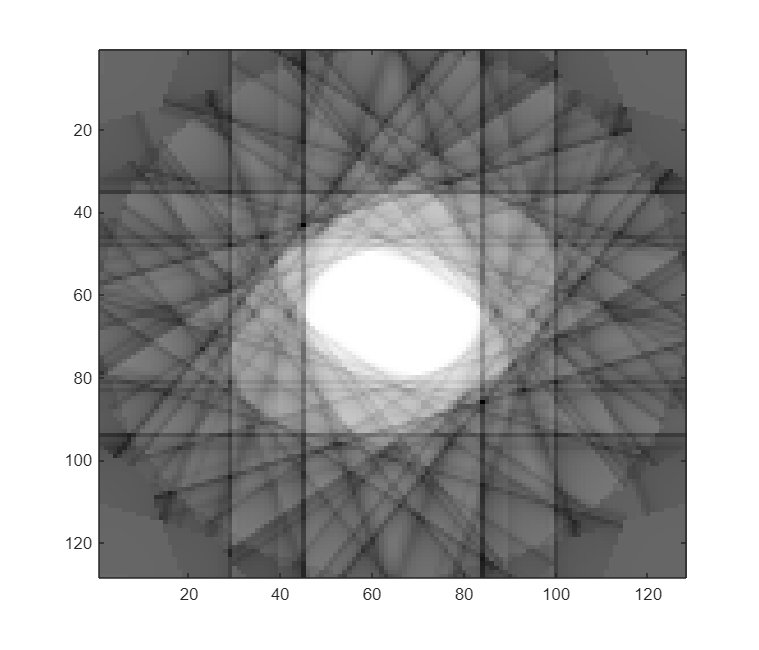

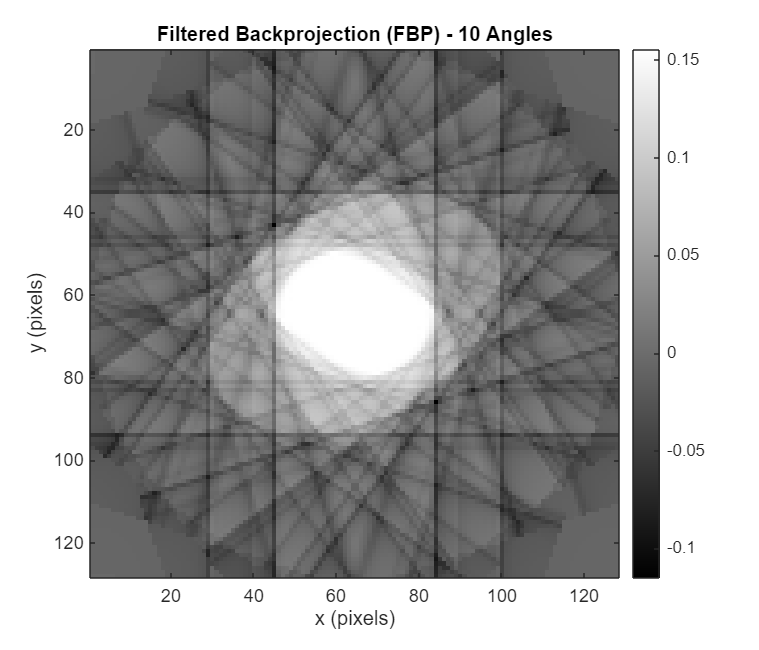

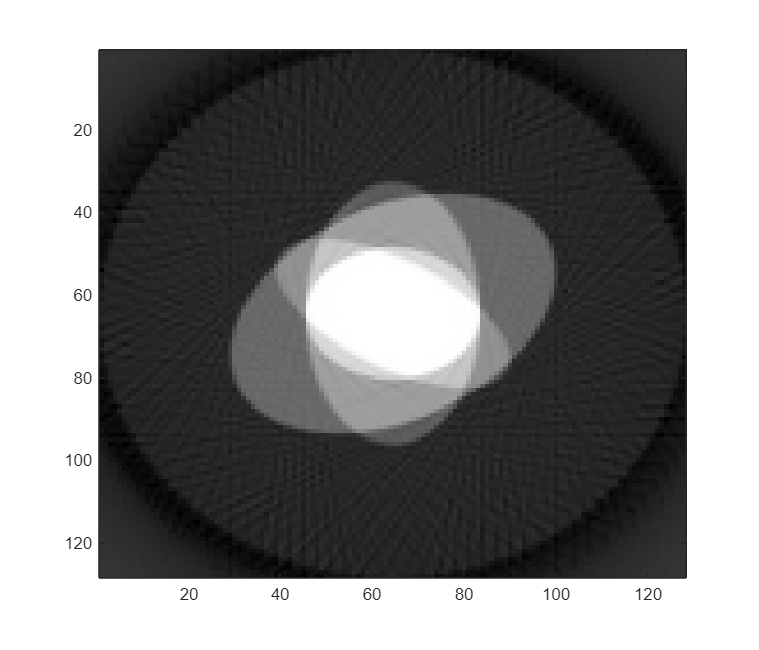

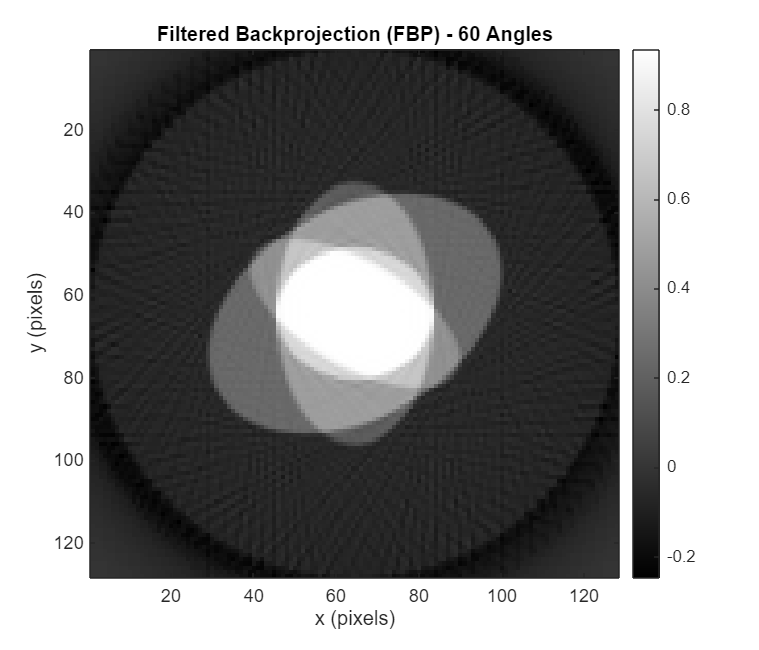

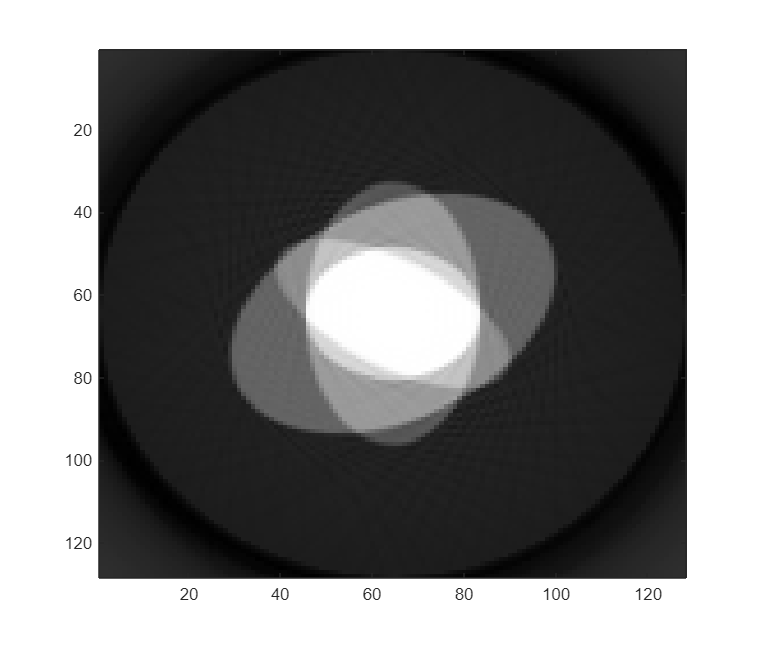

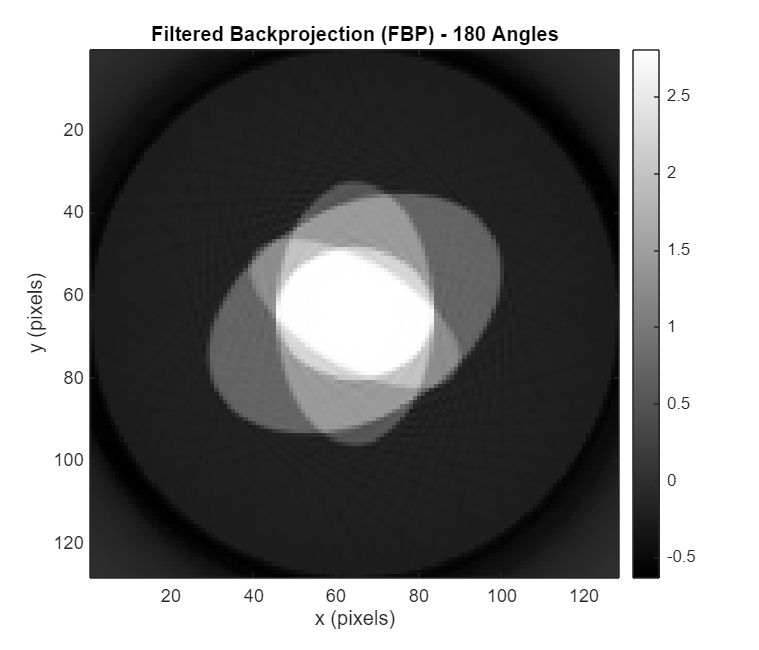

% 3.


angle_sets = [10, 60, 180];

for angle_idx = 1:length(angle_sets)
    n_angles = angle_sets(angle_idx);
    
    sino_filename = sprintf('sinogram_%d_angles.mat', n_angles);
    if ~exist(sino_filename, 'file')
        error('File %s not found. Run Problem 1 first.', sino_filename);
    end
    
    data = load(sino_filename);
    sinogram = data.sinogram;
    angles_deg = data.angles_deg;
    p = data.p;
    
    [n_ang, n_bins] = size(sinogram);
   
    sinogram_filtered = zeros(n_ang, n_bins);
    
    for i = 1:n_ang
        projection = sinogram(i, :);
       
        P = fft(projection);
        
        if mod(n_bins, 2) == 0
           
            rho = [0:(n_bins/2-1), -n_bins/2:-1] / n_bins;
        else
          
            rho = [0:(n_bins-1)/2, -(n_bins-1)/2:-1] / n_bins;
        end
        
        ramp_filter = abs(rho);
        P_filtered = P .* ramp_filter;
        projection_filtered = real(ifft(P_filtered));
        
        sinogram_filtered(i, :) = projection_filtered;
    end
    

    figure('Name', sprintf('Filtered Sinogram - %d angles', n_angles), ...
           'Position', [50 + angle_idx*60, 50, 700, 600]);
    imagesc(p, angles_deg, sinogram_filtered);
    colormap(gray);
    colorbar;
    title(sprintf('Filtered Sinogram (Ramp Filter Applied) - %d Angles', n_angles), ...
          'FontSize', 13, 'FontWeight', 'bold');
    xlabel('Detector Position p', 'FontSize', 12);
    ylabel('Angle \phi (degrees)', 'FontSize', 12);
    axis xy;
    set(gca, 'FontSize', 11);

    f_fbp = backproj(sinogram_filtered, angles_deg);
    
    fbp_filename = sprintf('fbp_%d_angles.mat', n_angles);
    save(fbp_filename, 'f_fbp', 'sinogram_filtered', 'n_angles');
    
    figure('Name', sprintf('Filtered Backprojection - %d angles', n_angles), ...
           'Position', [100 + angle_idx*60, 100, 700, 600]);
    imagesc(f_fbp);
    colormap(gray);
    colorbar;
    title(sprintf('Filtered Backprojection (FBP) - %d Angles', n_angles), ...
          'FontSize', 13, 'FontWeight', 'bold');
    xlabel('x (pixels)', 'FontSize', 12);
    ylabel('y (pixels)', 'FontSize', 12);
    axis image;
    set(gca, 'FontSize', 11);
    
end

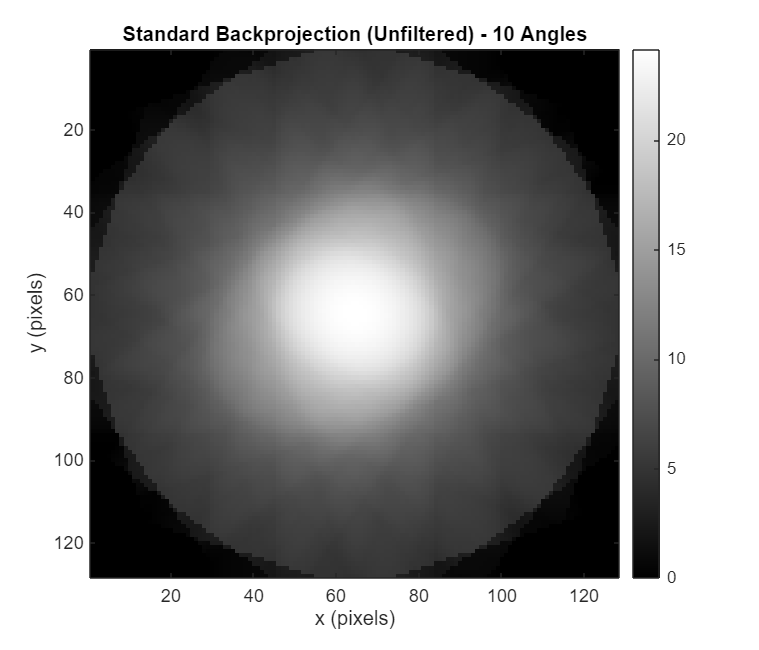

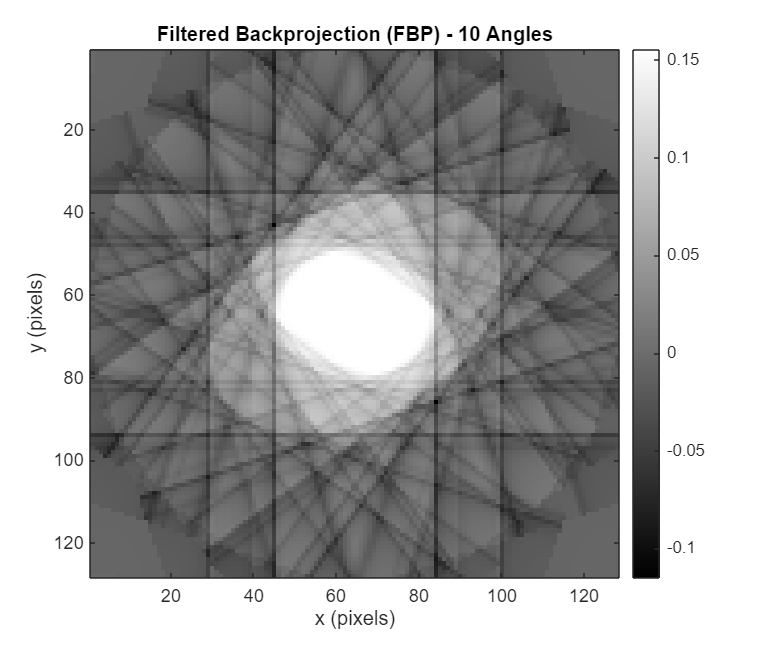

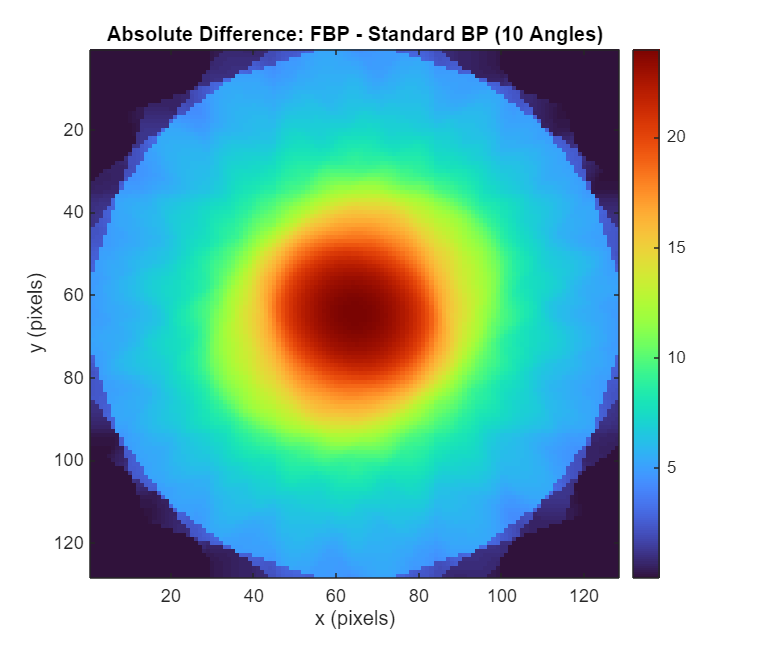

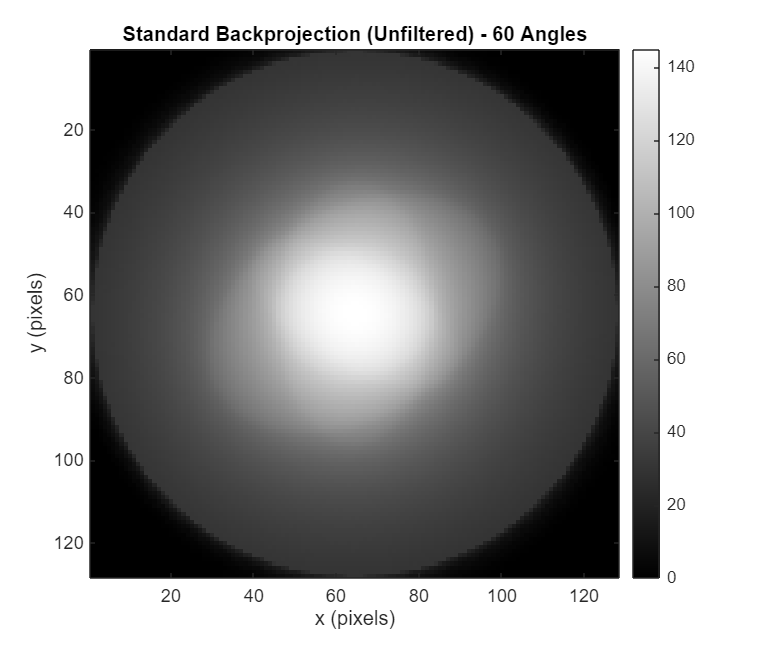

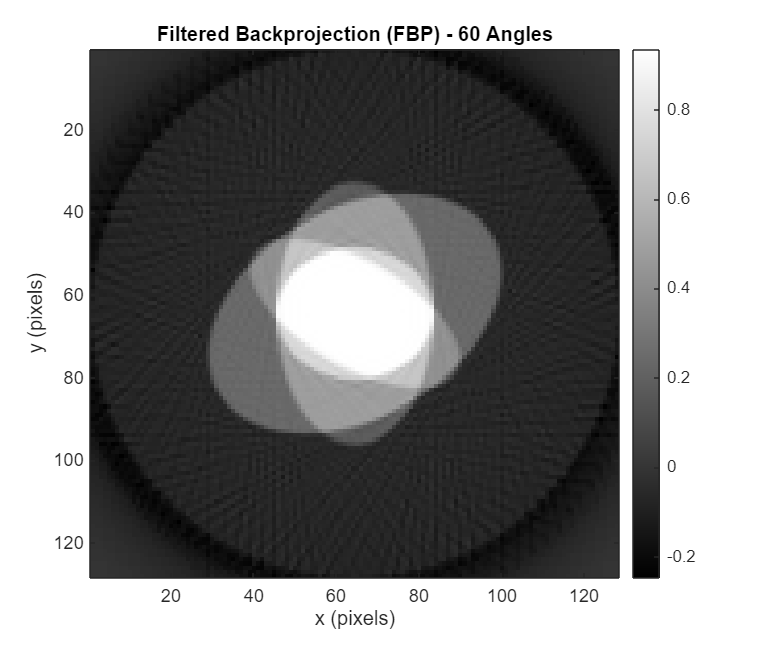

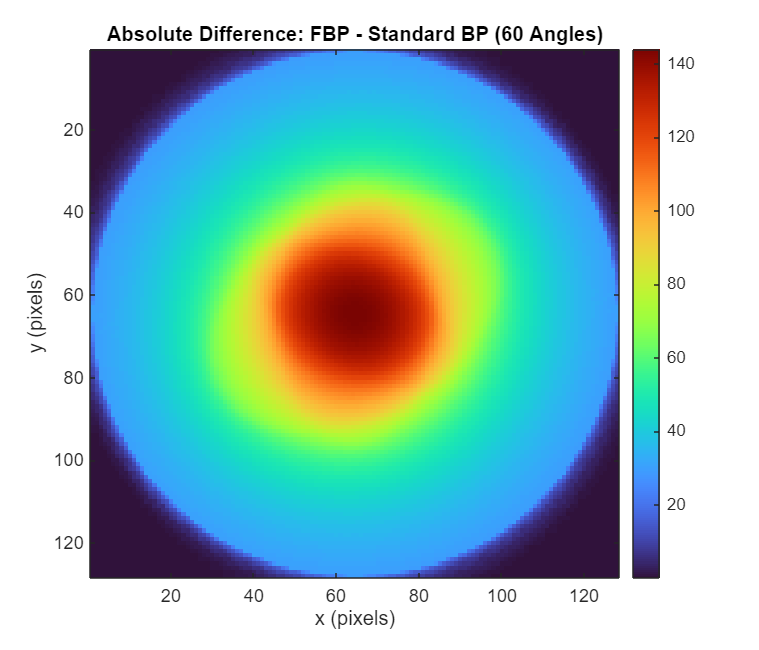

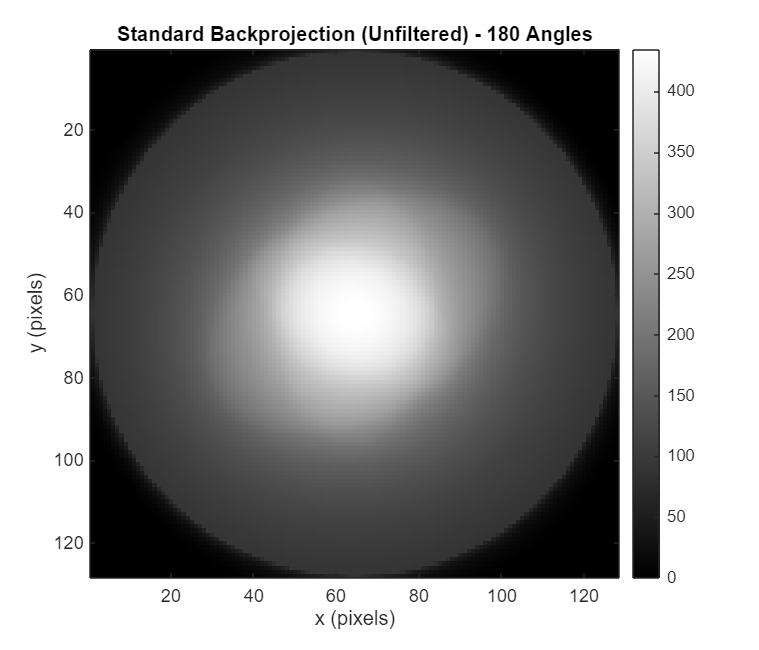

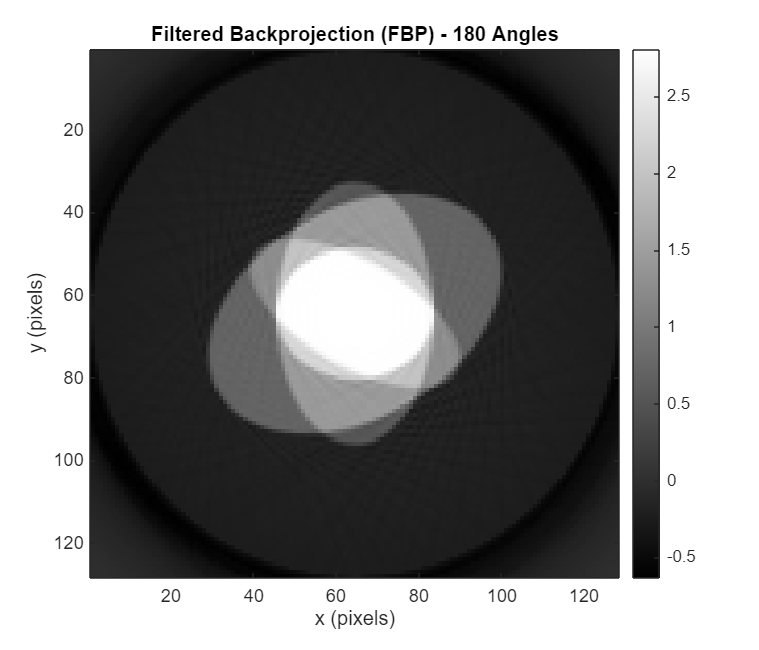


for angle_idx = 1:length(angle_sets)
    n_angles = angle_sets(angle_idx);
  
    bp_filename = sprintf('backproj_%d_angles.mat', n_angles);
    if ~exist(bp_filename, 'file')
        warning('Standard backprojection file %s not found. Run Question 2 first.', bp_filename);
        continue;
    end
    data_bp = load(bp_filename);
    f_backproj = data_bp.f_backproj;
    
    fbp_filename = sprintf('fbp_%d_angles.mat', n_angles);
    data_fbp = load(fbp_filename);
    f_fbp = data_fbp.f_fbp;

    figure('Name', sprintf('Standard BP - %d angles', n_angles), ...
           'Position', [150 + angle_idx*60, 150, 700, 600]);
    imagesc(f_backproj);
    colormap(gray);
    colorbar;
    title(sprintf('Standard Backprojection (Unfiltered) - %d Angles', n_angles), ...
          'FontSize', 13, 'FontWeight', 'bold');
    xlabel('x (pixels)', 'FontSize', 12);
    ylabel('y (pixels)', 'FontSize', 12);
    axis image;
    set(gca, 'FontSize', 11);
   
    figure('Name', sprintf('FBP - %d angles (comparison)', n_angles), ...
           'Position', [200 + angle_idx*60, 200, 700, 600]);
    imagesc(f_fbp);
    colormap(gray);
    colorbar;
    title(sprintf('Filtered Backprojection (FBP) - %d Angles', n_angles), ...
          'FontSize', 13, 'FontWeight', 'bold');
    xlabel('x (pixels)', 'FontSize', 12);
    ylabel('y (pixels)', 'FontSize', 12);
    axis image;
    set(gca, 'FontSize', 11);
    
    difference = abs(f_fbp - f_backproj);
    
    figure('Name', sprintf('Difference - %d angles', n_angles), ...
           'Position', [250 + angle_idx*60, 250, 700, 600]);
    imagesc(difference);
    colormap(turbo);
    colorbar;
    title(sprintf('Absolute Difference: FBP - Standard BP (%d Angles)', n_angles), ...
          'FontSize', 13, 'FontWeight', 'bold');
    xlabel('x (pixels)', 'FontSize', 12);
    ylabel('y (pixels)', 'FontSize', 12);
    axis image;
    set(gca, 'FontSize', 11);
   
end


n_angles = 180;

if exist('original_object.mat', 'file')
    orig_data = load('original_object.mat');
    f_original = orig_data.f_original;
    
    figure('Name', 'Original Object', 'Position', [300, 300, 700, 600]);
    imagesc(f_original);
    colormap(gray);
    colorbar;
    title('Original Object (Ground Truth)', 'FontSize', 14, 'FontWeight', 'bold');
    xlabel('x (pixels)', 'FontSize', 12);
    ylabel('y (pixels)', 'FontSize', 12);
    axis image;
    set(gca, 'FontSize', 11);
end

data_bp = load(sprintf('backproj_%d_angles.mat', n_angles));
f_backproj = data_bp.f_backproj;

data_fbp = load(sprintf('fbp_%d_angles.mat', n_angles));
f_fbp = data_fbp.f_fbp;

figure('Name', 'Horizontal Profile Comparison', 'Position', [350, 350, 900, 600]);
center = ceil(size(f_backproj, 1) / 2);

plot(f_backproj(center, :), 'b-', 'LineWidth', 2, 'DisplayName', 'Standard BP');
hold on;
plot(f_fbp(center, :), 'r-', 'LineWidth', 2, 'DisplayName', 'FBP');

if exist('f_original', 'var')
    plot(f_original(center, :), 'k--', 'LineWidth', 2, 'DisplayName', 'Original');
end

grid on;
legend('Location', 'best', 'FontSize', 11);
xlabel('x position (pixels)', 'FontSize', 12);
ylabel('Intensity', 'FontSize', 12);
title('Horizontal Profile through Center (180 Angles)', 'FontSize', 14, 'FontWeight', 'bold');
set(gca, 'FontSize', 11);

figure('Name', 'Vertical Profile Comparison', 'Position', [400, 400, 900, 600]);

plot(f_backproj(:, center), 'b-', 'LineWidth', 2, 'DisplayName', 'Standard BP');
hold on;
plot(f_fbp(:, center), 'r-', 'LineWidth', 2, 'DisplayName', 'FBP');

if exist('f_original', 'var')
    plot(f_original(:, center), 'k--', 'LineWidth', 2, 'DisplayName', 'Original');
end

grid on;
legend('Location', 'best', 'FontSize', 11);
xlabel('y position (pixels)', 'FontSize', 12);
ylabel('Intensity', 'FontSize', 12);
title('Vertical Profile through Center (180 Angles)', 'FontSize', 14, 'FontWeight', 'bold');
set(gca, 'FontSize', 11);

% 4.

% Projections from 0 to π contain all necessary mathematical information for reconstruction
% By acquiring redundant measurements at angles phi and phi+pi, we can average them
% Averaging independent noise measurements reduces noise by a factor of sqrt(2)
% This improves the signal to noise ratio (SNR) without increasing radiation dose per projection
% Each detector element traces out specific paths through the reconstruction
% With 0 to π data only, detector errors map directly to rings
% With 0 to 2π data, averaging redundant measurements suppresses ring artifacts
% The redundancy provides an internal consistency check